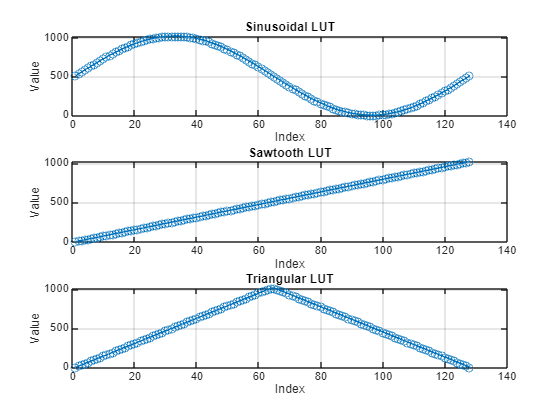

% Define the number of samples
num_samples = 128;

% Define the range of the LUT values
max_value = 1023;

% Generate the sinusoidal LUT
x = linspace(0, 2*pi, num_samples);
sin_lut = round((sin(x) + 1) * (max_value / 2));

% Generate the sawtooth wave LUT
saw_lut = round(linspace(0, max_value, num_samples));

% Generate the triangular wave LUT
tri_lut = round([2 * (0:num_samples/2-1) * (max_value / (num_samples - 1)), 2 * (num_samples/2-1:-1:0) * (max_value / (num_samples - 1))]);

% Plot the LUTs
figure;

% Plot Sinusoidal LUT
subplot(3,1,1);
plot(sin_lut, '-o');
title('Sinusoidal LUT');
xlabel('Index');
ylabel('Value');
grid on;

% Plot Sawtooth LUT
subplot(3,1,2);
plot(saw_lut, '-o');
title('Sawtooth LUT');
xlabel('Index');
ylabel('Value');
grid on;

% Plot Triangular LUT
subplot(3,1,3);
plot(tri_lut, '-o');
title('Triangular LUT');
xlabel('Index');
ylabel('Value');
grid on;


% Output LUTs in C array format
fprintf('Sinusoidal LUT:\n');

Sinusoidal LUT:


fprintf('const uint16_t sin_lut[%d] = {', num_samples);

const uint16_t sin_lut[128] = {

fprintf('%d, ', sin_lut(1:end));

512, 537, 562, 587, 612, 637, 661, 685, 709, 732, 754, 776, 798, 818, 838, 857, 875, 893, 909, 925, 939, 952, 965, 976, 986, 995, 1002, 1009, 1014, 1018, 1021, 1023, 1023, 1022, 1020, 1016, 1012, 1006, 999, 990, 981, 970, 959, 946, 932, 917, 901, 884, 866, 848, 828, 808, 787, 765, 743, 720, 697, 673, 649, 624, 600, 575, 549, 524, 499, 474, 448, 423, 399, 374, 350, 326, 303, 280, 258, 236, 215, 195, 175, 157, 139, 122, 106, 91, 77, 64, 53, 42, 33, 24, 17, 11, 7, 3, 1, 0, 0, 2, 5, 9, 14, 21, 28, 37, 47, 58, 71, 84, 98, 114, 130, 148, 166, 185, 205, 225, 247, 269, 291, 314, 338, 362, 386, 411, 436, 461, 486, 511, 


fprintf('Sawtooth LUT:\n');

Sawtooth LUT:


fprintf('const uint16_t saw_lut[%d] = {', num_samples);

const uint16_t saw_lut[128] = {

fprintf('%d, ', saw_lut(1:end));

0, 8, 16, 24, 32, 40, 48, 56, 64, 72, 81, 89, 97, 105, 113, 121, 129, 137, 145, 153, 161, 169, 177, 185, 193, 201, 209, 217, 226, 234, 242, 250, 258, 266, 274, 282, 290, 298, 306, 314, 322, 330, 338, 346, 354, 362, 371, 379, 387, 395, 403, 411, 419, 427, 435, 443, 451, 459, 467, 475, 483, 491, 499, 507, 516, 524, 532, 540, 548, 556, 564, 572, 580, 588, 596, 604, 612, 620, 628, 636, 644, 652, 661, 669, 677, 685, 693, 701, 709, 717, 725, 733, 741, 749, 757, 765, 773, 781, 789, 797, 806, 814, 822, 830, 838, 846, 854, 862, 870, 878, 886, 894, 902, 910, 918, 926, 934, 942, 951, 959, 967, 975, 983, 991, 999, 1007, 1015, 1023, 


fprintf('Triangular LUT:\n');

Triangular LUT:


fprintf('const uint16_t tri_lut[%d] = {', num_samples);

const uint16_t tri_lut[128] = {

fprintf('%d, ', tri_lut(1:end));

0, 16, 32, 48, 64, 81, 97, 113, 129, 145, 161, 177, 193, 209, 226, 242, 258, 274, 290, 306, 322, 338, 354, 371, 387, 403, 419, 435, 451, 467, 483, 499, 516, 532, 548, 564, 580, 596, 612, 628, 644, 661, 677, 693, 709, 725, 741, 757, 773, 789, 806, 822, 838, 854, 870, 886, 902, 918, 934, 951, 967, 983, 999, 1015, 1015, 999, 983, 967, 951, 934, 918, 902, 886, 870, 854, 838, 822, 806, 789, 773, 757, 741, 725, 709, 693, 677, 661, 644, 628, 612, 596, 580, 564, 548, 532, 516, 499, 483, 467, 451, 435, 419, 403, 387, 371, 354, 338, 322, 306, 290, 274, 258, 242, 226, 209, 193, 177, 161, 145, 129, 113, 97, 81, 64, 48, 32, 16, 0, 